%Project 8 - Streetlight Brightness Model
%Benjamin Oakes - Engineering Computer Applications

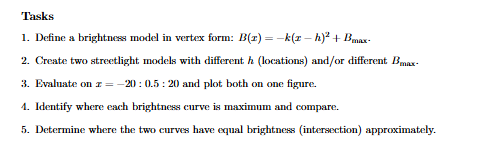

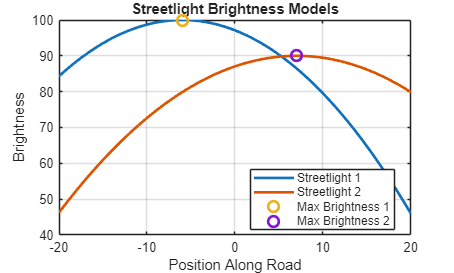


% Clears all variables from the workspace
clear;

% Clears the command window
clc;

% Closes all open figure windows
close all;

% Creates a vector of road positions from -20 to 20
x = -20:0.5:20;

% Streetlight 1 parameters
k1 = 0.08;
h1 = -6;
Bmax1 = 100;

% Streetlight 2 parameters
k2 = 0.06;
h2 = 7;
Bmax2 = 90;

% Calculates brightness values for both streetlights
B1 = -k1 .* (x - h1).^2 + Bmax1;
B2 = -k2 .* (x - h2).^2 + Bmax2;

% Prevents negative brightness values
B1(B1 < 0) = 0;
B2(B2 < 0) = 0;

% Finds maximum brightness values and locations
[maxB1, index1] = max(B1);
maxLocation1 = x(index1);

[maxB2, index2] = max(B2);
maxLocation2 = x(index2);

% Calculates difference between brightness curves
difference = B1 - B2;

% Finds where the curves intersect
intersectionIndex = find(difference(1:end-1) .* difference(2:end) <= 0);

% Creates empty array for intersection points
intersectionPoints = [];

% Loops through possible intersections
for i = intersectionIndex
    
    % Gets x-values around intersection
    x1 = x(i);
    x2 = x(i+1);
    
    % Gets y-values around intersection
    y1 = difference(i);
    y2 = difference(i+1);
    
    % Uses interpolation to estimate exact intersection
    xIntersect = x1 - y1 * (x2 - x1) / (y2 - y1);
    
    % Stores intersection point
    intersectionPoints = [intersectionPoints xIntersect];
end

% Creates first figure
figure;

% Plots brightness model for streetlight 1
plot(x, B1, 'LineWidth', 2);

% Keeps graph active
hold on;

% Plots brightness model for streetlight 2
plot(x, B2, 'LineWidth', 2);

% Marks maximum brightness point for streetlight 1
plot(maxLocation1, maxB1, 'o', 'MarkerSize', 8, 'LineWidth', 2);

% Marks maximum brightness point for streetlight 2
plot(maxLocation2, maxB2, 'o', 'MarkerSize', 8, 'LineWidth', 2);

% Turns grid on
grid on;

% Adds title and labels
title('Streetlight Brightness Models');
xlabel('Position Along Road');
ylabel('Brightness');

% Adds legend
legend('Streetlight 1', ...
       'Streetlight 2', ...
       'Max Brightness 1', ...
       'Max Brightness 2', ...
       'Location', 'best');

% Saves figure
saveas(gcf, 'project7_brightness_models.png');

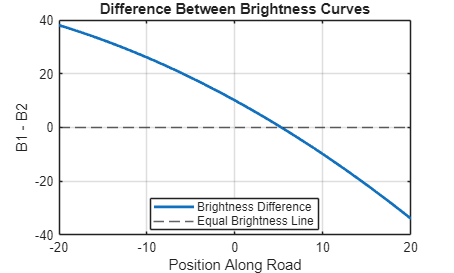


% Creates second figure
figure;

% Plots difference between curves
plot(x, difference, 'LineWidth', 2);

% Keeps graph active
hold on;

% Draws horizontal line at y = 0
yline(0, '--');

% Turns grid on
grid on;

% Adds title and labels
title('Difference Between Brightness Curves');
xlabel('Position Along Road');
ylabel('B1 - B2');

% Adds legend
legend('Brightness Difference', ...
       'Equal Brightness Line', ...
       'Location', 'best');

% Saves second figure
saveas(gcf, 'project7_brightness_difference.png');


% Creates results table
resultsTable = table(x', B1', B2', difference', ...
    'VariableNames', ...
    {'Position', 'Brightness1', 'Brightness2', 'Difference'});

% Displays table
disp(resultsTable);

    Position    Brightness1    Brightness2    Difference
    ________    ___________    ___________    __________

       -20         84.32          46.26          38.06  
     -19.5         85.42         47.865         37.555  
       -19         86.48          49.44          37.04  
     -18.5          87.5         50.985         36.515  
       -18         88.48           52.5          35.98  
     -17.5         89.42         53.985         35.435  
       -17         90.32          55.44          34.88  
     -16.5         91.18         56.865         34.315  
       -16            92          58.26          33.74  
     -15.5         92.78         59.625         33.155  
       -15         93.52          60.96          32.56  
     -14.5         94.22         62.265         31.955  
       -14         94.88          63.54          31.34  
     -13


% Displays important results
fprintf('Streetlight 1 maximum brightness occurs at x = %.2f.\n', maxLocation1);

Streetlight 1 maximum brightness occurs at x = -6.00.


fprintf('Streetlight 1 maximum brightness is %.2f.\n', maxB1);

Streetlight 1 maximum brightness is 100.00.



fprintf('Streetlight 2 maximum brightness occurs at x = %.2f.\n', maxLocation2);

Streetlight 2 maximum brightness occurs at x = 7.00.


fprintf('Streetlight 2 maximum brightness is %.2f.\n', maxB2);

Streetlight 2 maximum brightness is 90.00.



% Checks if intersections exist
if isempty(intersectionPoints)
    
    fprintf('No equal brightness points were found in the road range.\n');
    
else
    
    fprintf('Approximate equal brightness point(s):\n');
    disp(intersectionPoints);
    
end

Approximate equal brightness point(s):


    5.2786

